# Mean Activity

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze
%Prefix = '2020-02-23-optoknirps_new_embryo6';
%Prefix = '2020-02-21-optoknirps_new_embryo5'; % with export
Prefix = '2020-02-23-optoknirps_new_embryo7'; % Y->N
%Prefix = '2020-03-04-optoknirps_new_embryo10'; % N->Y

Variables depending on the data

- Start/Final frames

% WT: embryo6
%start_frame = 40;
%final_frame = 149;

% with export: embryo5
%start_frame = 20;
%final_frame = 124;

% Y->N: embryo7
start_frame = 55;
final_frame = 157;

% N->Y
%start_frame = 10;
%final_frame = 120;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['/Users/jiaxi.zhao/Dropbox/OptoDropbox/#analysis/202004 - perturbation analysis/with_export/figure/' Prefix];

mkdir(FigPath)


% Specify the position of DynamicsResults folder
DynamicsResultsFolder = '/Users/jiaxi.zhao/Dropbox/OptoDropbox';

Now, load all the data

% Now we'll load the CompiledParticles dataset
% This generates a string that gives the path to CompiledParticles
LoadParticlePath = [DynamicsResultsFolder '/' Prefix '/CompiledParticles.mat']; 
%LoadNucleiPath = [DynamicsResultsFolder '/' Prefix '/' Prefix '_lin.mat'];
LoadComNucleiPath = [DynamicsResultsFolder '/' Prefix '/CompiledNuclei.mat']; 

data.particle = load(LoadParticlePath);
data.nuclei = load(LoadComNucleiPath);
%load(LoadNucleiPath)

ElapsedTime = data.particle.ElapsedTime-data.particle.ElapsedTime(start_frame);
Time = ElapsedTime(start_frame:final_frame);
APbinID = data.particle.APbinID;

## Draw figures for particles

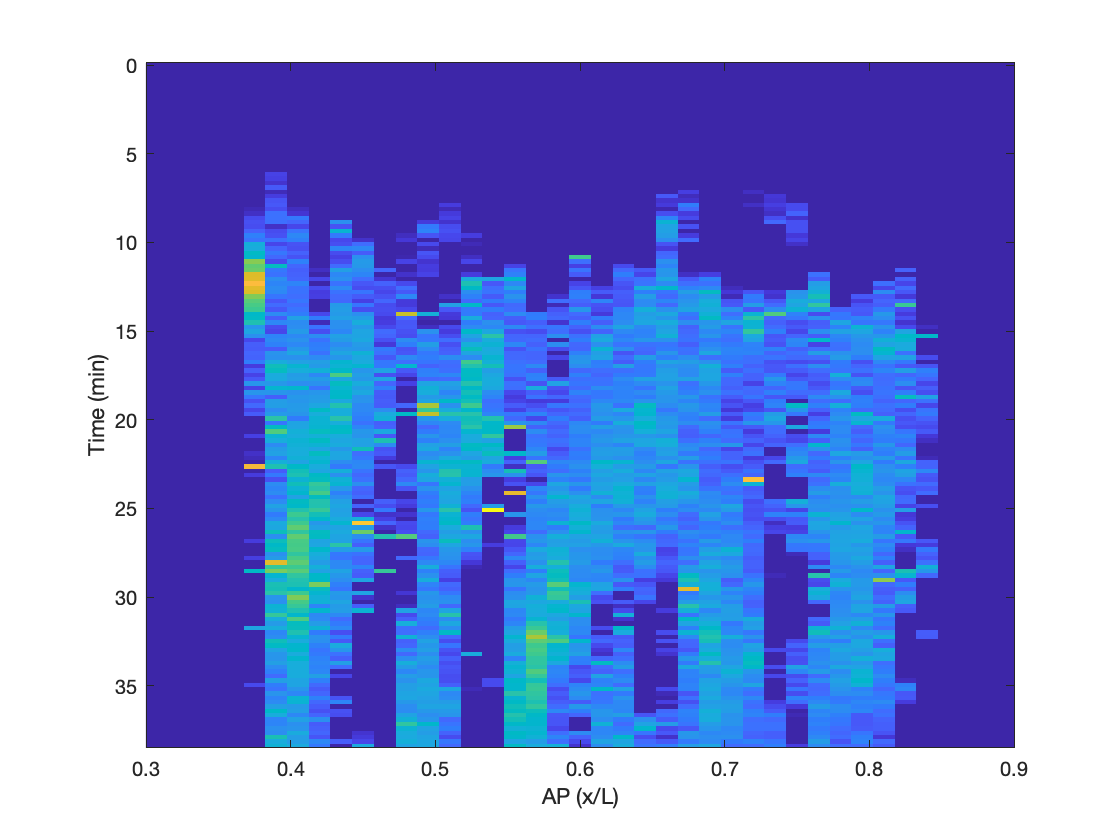

MeanFig = figure;
imagesc(APbinID,Time,data.particle.MeanVectorAP{1});
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([0.3 0.9])

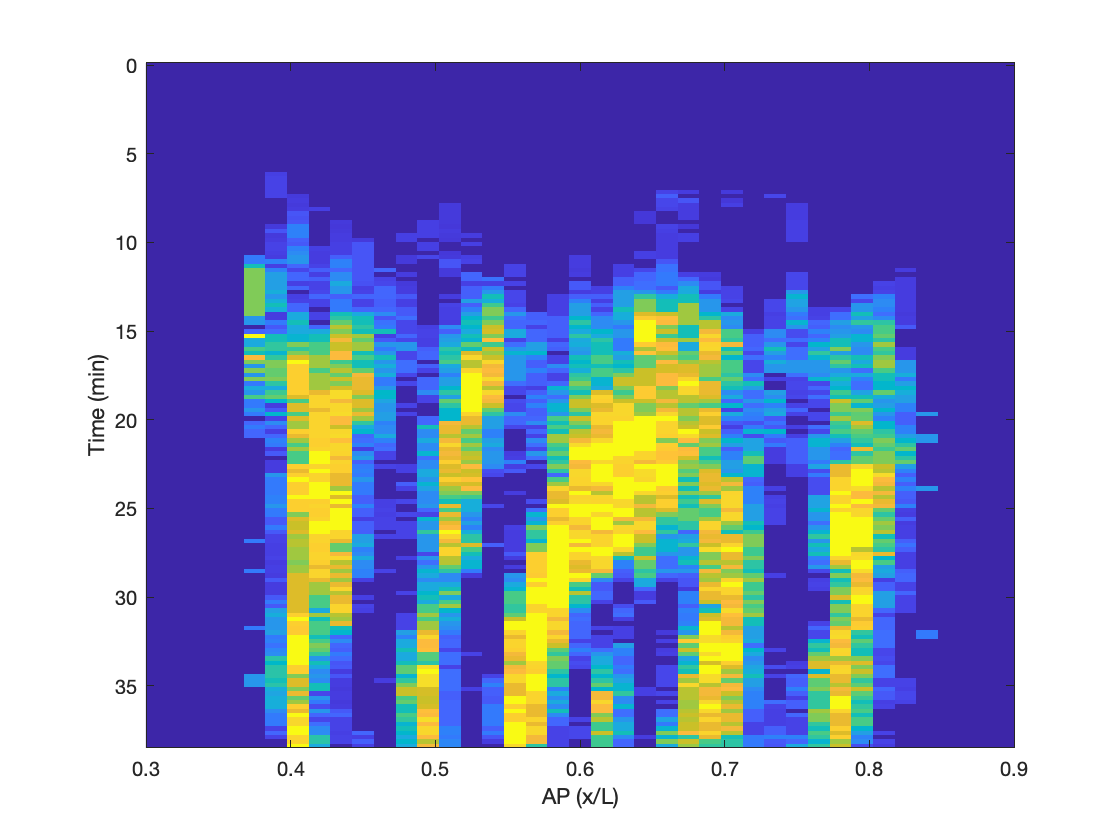

OnFig = figure;
imagesc(APbinID,Time,data.particle.OnRatioAP{1});
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([0.3 0.9])

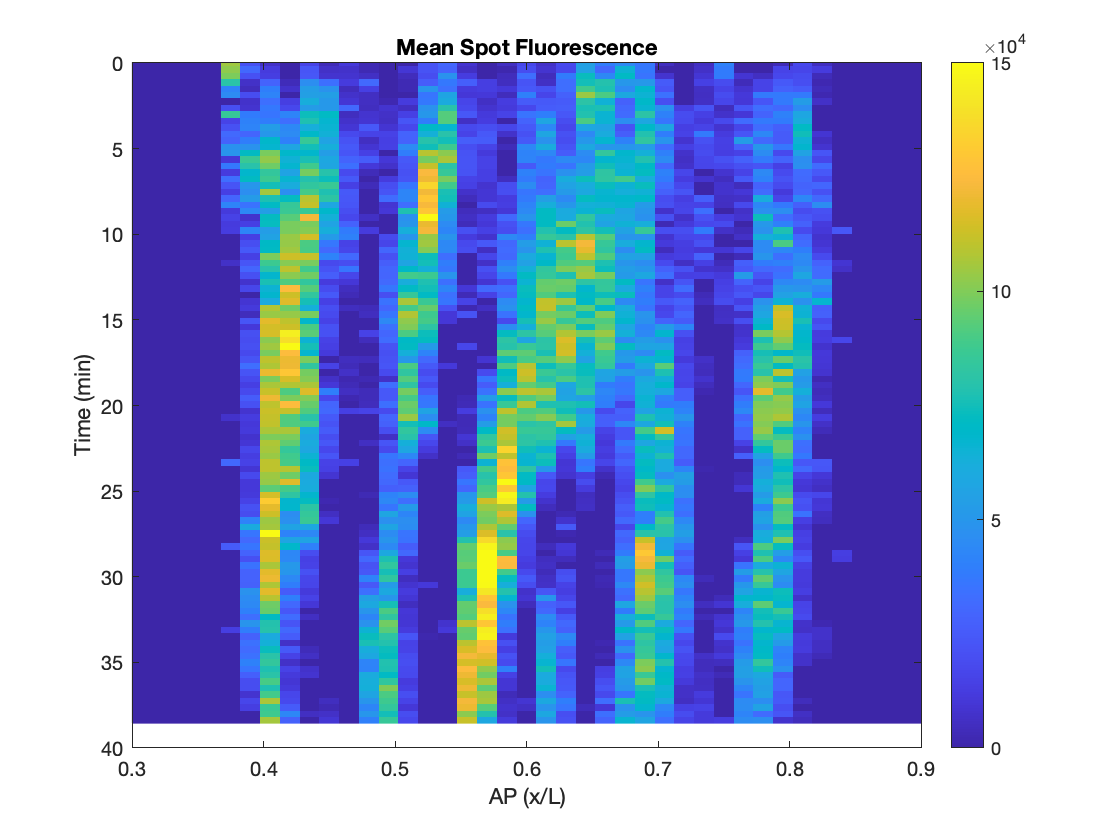

data_plot = data.particle.OnRatioAP{1}.*data.particle.MeanVectorAP{1};

MeanAllFig = figure;
imagesc(APbinID,Time,data_plot(start_frame:final_frame,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([0.3 0.9])
ylim([0 40])
title('Mean Spot Fluorescence')
colorbar
caxis([0 1.5E5])
saveas(MeanAllFig,[FigPath '/MeanSpot_fluo.pdf' ]);

## Draw figures for nuclei

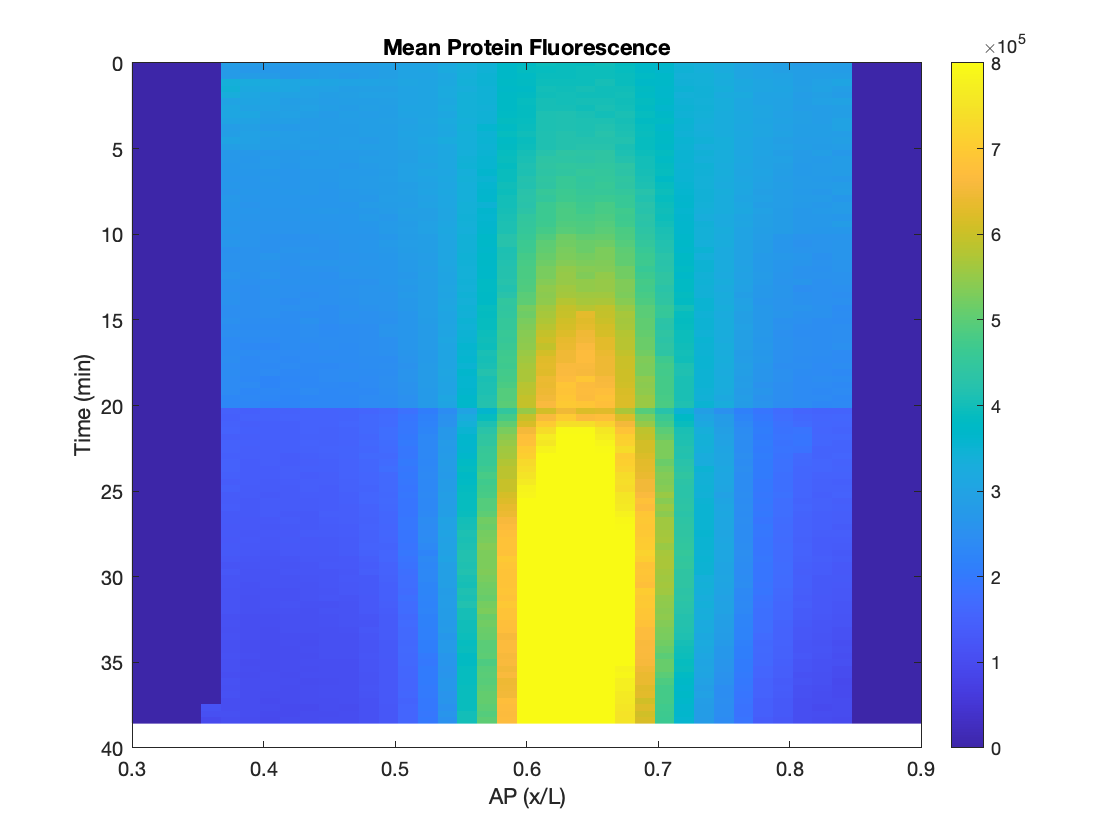

data_plot = data.nuclei.MeanVectorAP;

MeanNucleiFig = figure;
imagesc(APbinID,Time,data_plot(start_frame:final_frame,:));
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([0.3 0.9])
ylim([0 40])
colorbar
caxis([0 8E5])
title('Mean Protein Fluorescence')
saveas(MeanNucleiFig,[FigPath '/MeanProtein_fluo.pdf' ]);

## Plot them both together

Plot for bin 40-...

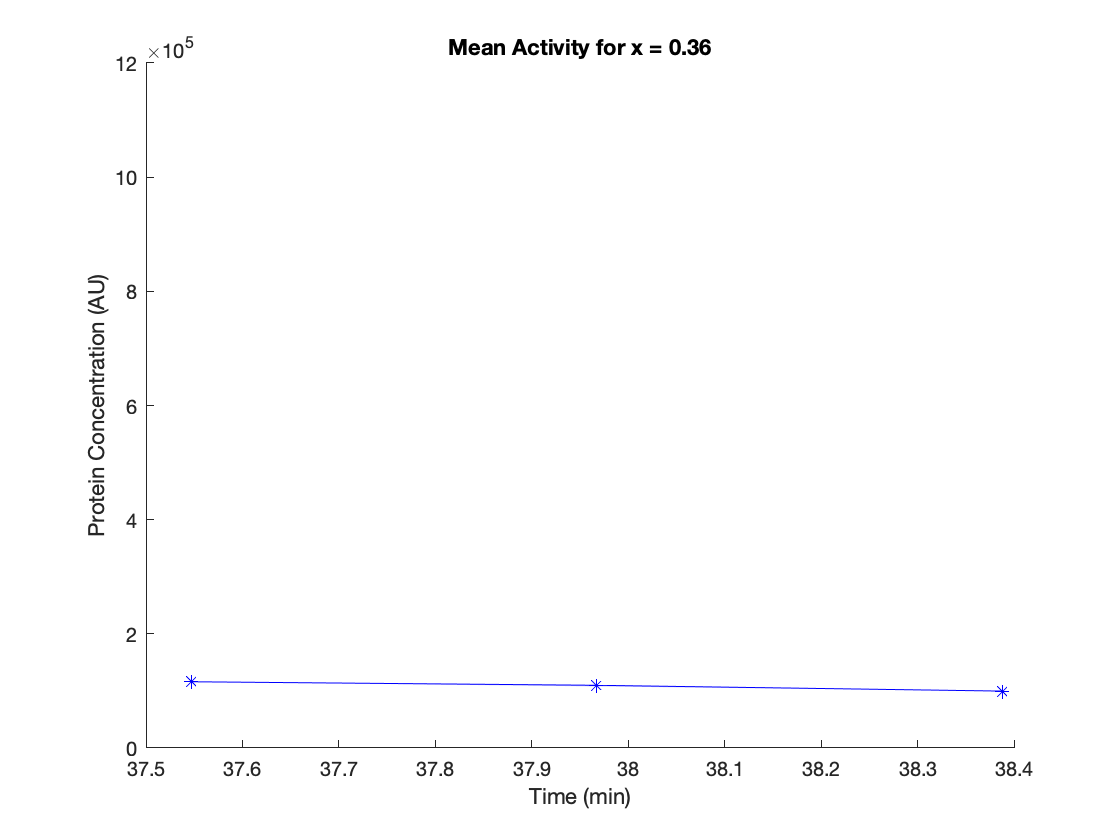

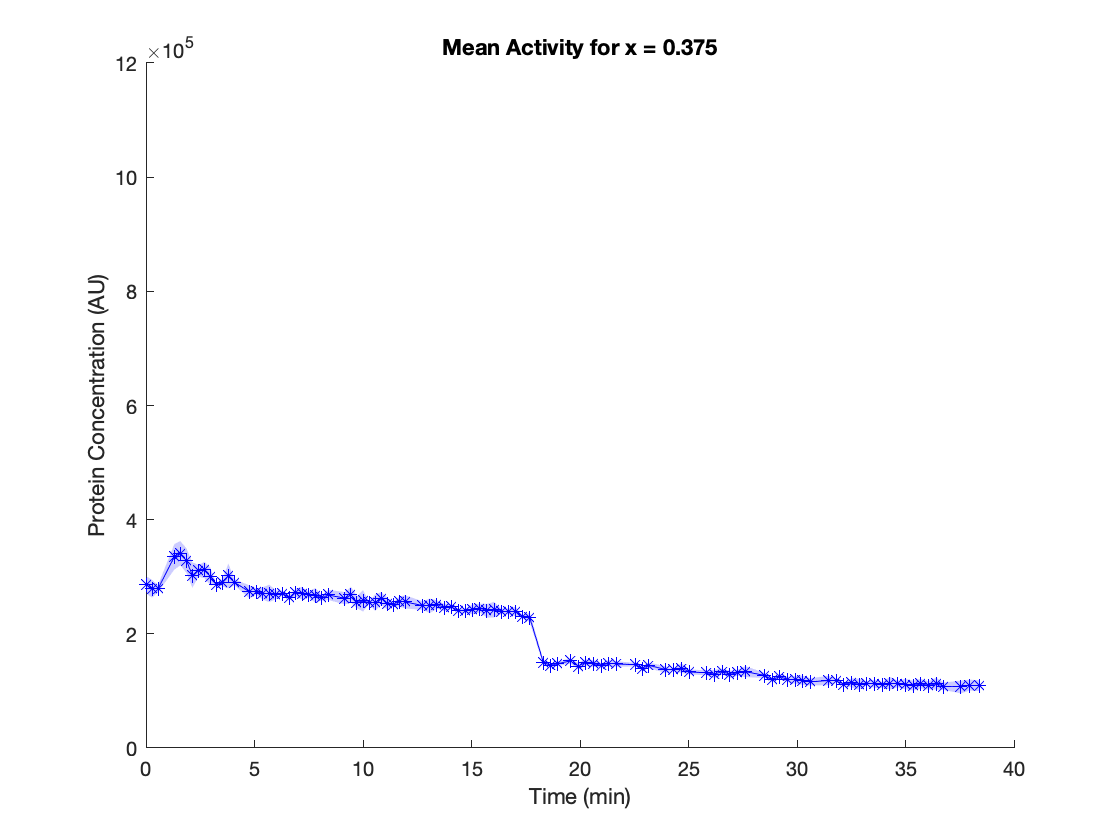

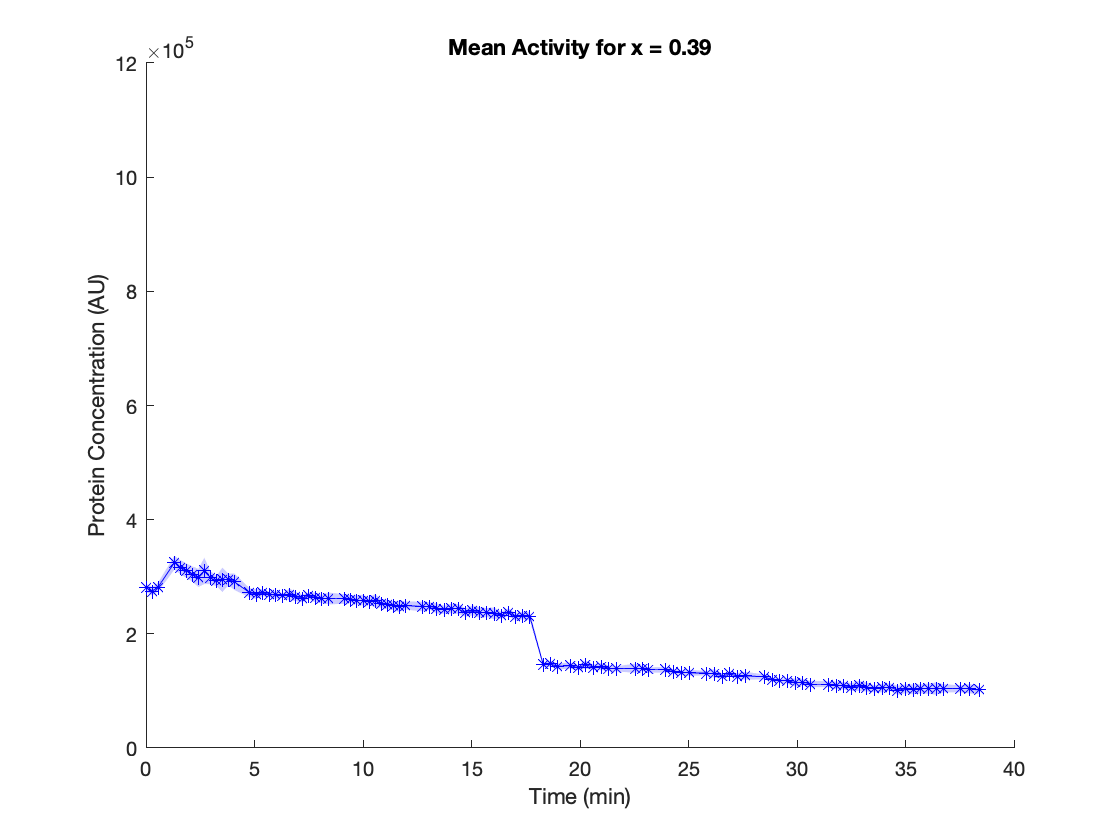

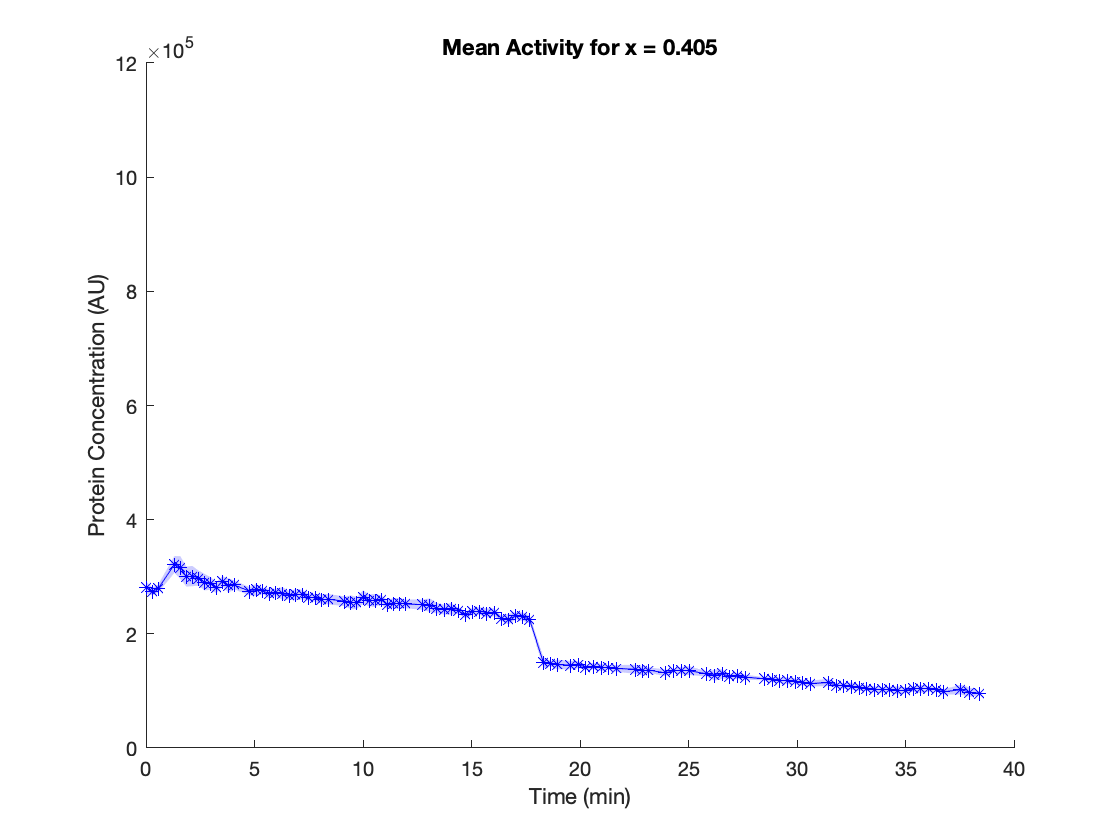

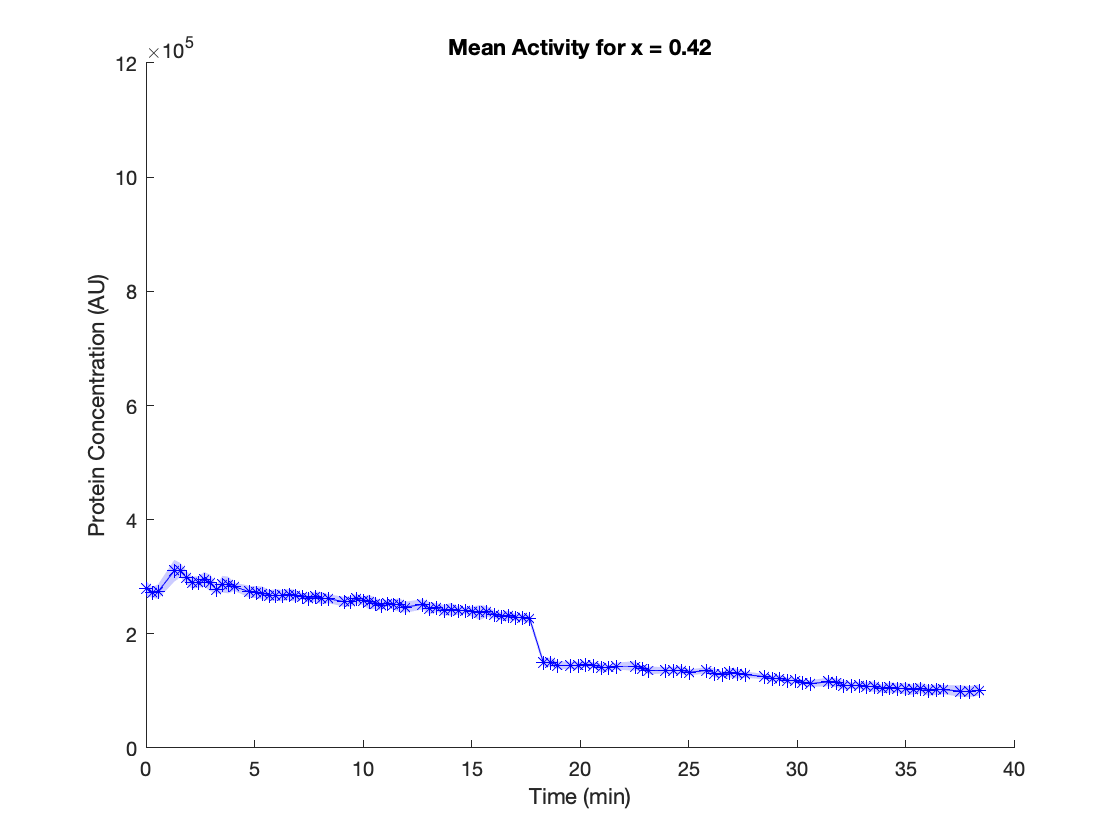

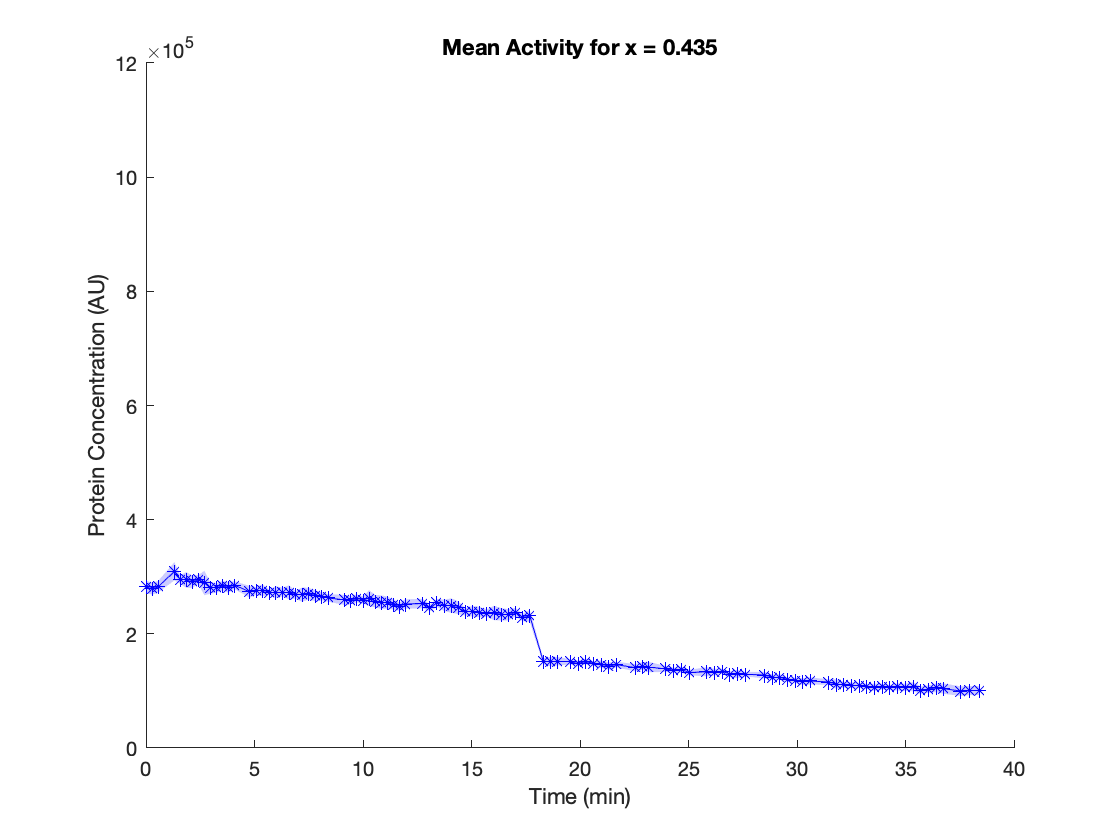

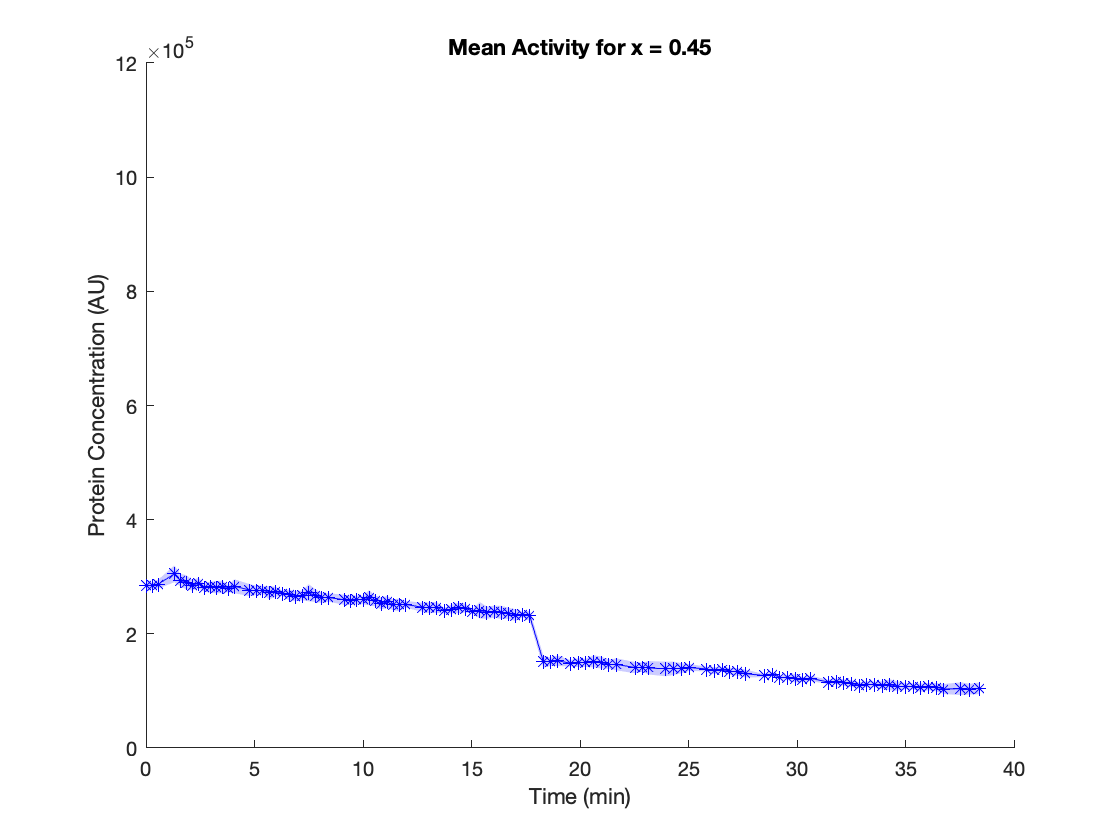

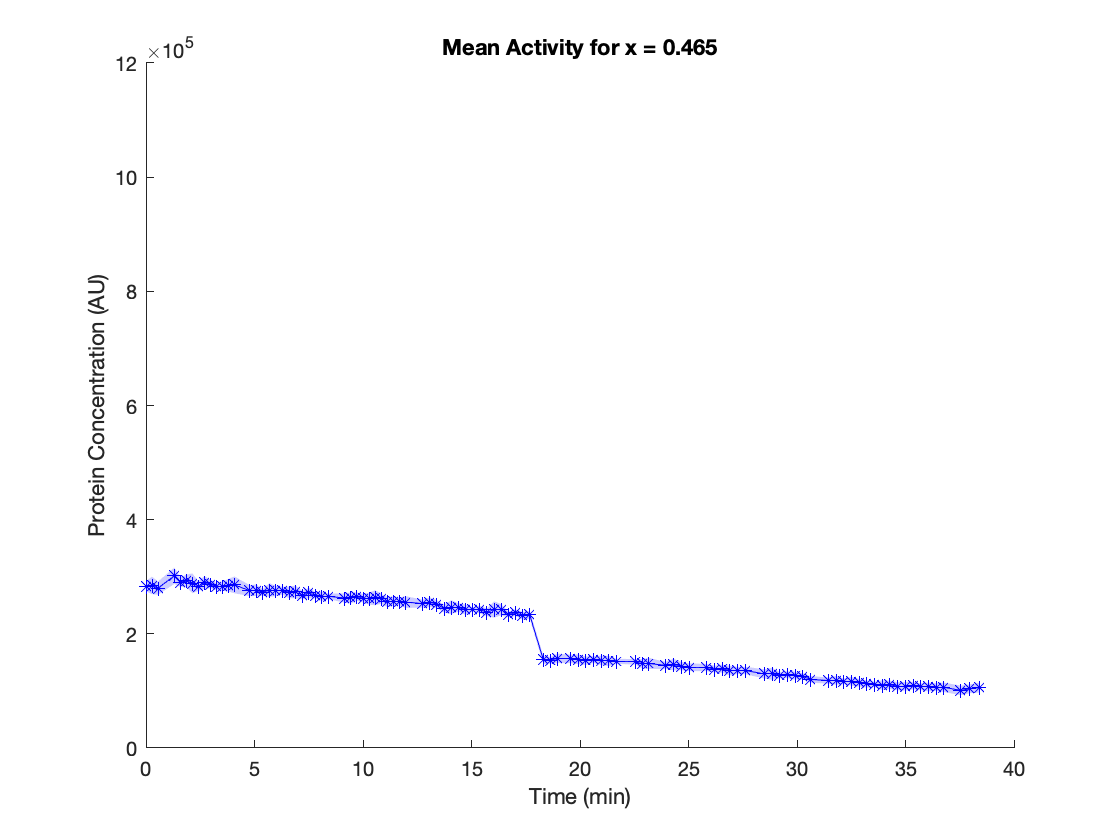

Index in position 2 exceeds array bounds.

Error in singlepatch (line 35)
if all(sz(:,1) == 1)

Error in boundedline>calcpatch (li

%for i = 39:47
for i = 25:58
    
    APbin_temp = i;
    particle_temp = data.particle.MeanVectorAP{1}(start_frame:final_frame,APbin_temp).*data.particle.OnRatioAP{1}(start_frame:final_frame,APbin_temp);
    error_particle_temp = data.particle.SDVectorAP{1}(start_frame:final_frame,APbin_temp).*data.particle.OnRatioAP{1}(start_frame:final_frame,APbin_temp);
    protein_temp = data.nuclei.MeanVectorAP(start_frame:final_frame,APbin_temp);
    error_protein_temp = data.nuclei.SDVectorAP(start_frame:final_frame,APbin_temp);
    
    OverlayFig = figure;
    xlabel('Time (min)')
    title(['Mean Activity for x = ' num2str(APbinID(APbin_temp))])
    %yyaxis left
    boundedline(Time, protein_temp,error_protein_temp, '-b*','nan', 'gap','alpha');
    ylabel('Protein Concentration (AU)')
    ylim([0E5 12E5])
    %yyaxis right
    %boundedline(Time, particle_temp,error_particle_temp, '-r*','nan', 'gap','alpha');
    %ylabel('Mean Transcriptional Activity (AU)')
    %ylim([0 2E5])
    
    saveas(OverlayFig,[FigPath '/mean_traces/bin_' num2str(i) '.pdf'])
end